## **PROBLEM 1**

The equivalent homogenous transformation for these set of rotations is given by,

R = R1*R2*R3

where R1 = $\left\lbrack \begin{array}{cccc}
\cos {\left(45\right)}^o  & -\sin {\left(45\right)}^o  & 0 & 0\\
\sin {\left(45\right)}^o  & \cos {\left(45\right)}^o  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

R2 = $\left\lbrack \begin{array}{cccc}
\cos {\left(30\right)}^o  & 0 & \sin {\left(30\right)}^o  & 0\\
0 & 1 & 0 & 0\\
-\sin {\left(30\right)}^o  & 0 & \cos {\left(30\right)}^o  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

R3 = $\left\lbrack \begin{array}{cccc}
\cos {\left(20\right)}^o  & -\sin {\left(20\right)}^o  & 0 & 0\\
\sin {\left(20\right)}^o  & \cos {\left(20\right)}^o  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

clear all

R1 = [[cosd(45) -sind(45) 0 0];
      [sind(45) cosd(45) 0 0];
      [0 0 1 0];
      [0 0 0 1]];
R2 = [[cosd(30) 0 sind(30) 0];
      [0 1 0 0];
      [-sind(30) 0 cosd(30) 0];
      [0 0 0 1]];
R3 = [[cosd(20) -sind(20) 0 0];
      [sind(20) cosd(20) 0 0];
      [0 0 1 0];
      [0 0 0 1]];
R = R1*R2*R3;

R = $\left\lbrack \begin{array}{cccc}
0\ldotp 3336 & -0\ldotp 8379 & 0\ldotp 3536 & 0\\
0\ldotp 8173 & 0\ldotp 4550 & 0\ldotp 3536 & 0\\
-0\ldotp 4698 & 0\ldotp 1710 & 0\ldotp 8660 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

**(A)** Since this is a case of pure rotation, let's consider only the rotation matrix,

r10 = [[0.3336 -0.8379 0.3536];
     [0.8173 0.4550 0.3536];
     [-0.4698 0.1710 0.8660]];
r0 = [[1 0 0];
      [0 1 0];
      [0 0 1]];

% time steps are from t=0 to t=10, in steps of 2
t = (2:2:8)';
r_int = zeros(3,3,4);
% interpolating each element of the matrix linearly
for i = (1:1:length(t))
    T = t(i,1);
    for j = (1:1:size(r0,1))
        for k = (1:1:size(r0,2))
            r_int(j,k,i) = (((r10(j,k)-r0(j,k))/(10))*T)+r0(j,k);            
        end
    end
end
r2 = r_int(:,:,1); % intermediate rotation matrix at t=2s
r4 = r_int(:,:,2); % intermediate rotation matrix at t=4s
r6 = r_int(:,:,3); % intermediate rotation matrix at t=6s
r8 = r_int(:,:,4); % intermediate rotation matrix at t=8s

figure;
view([170 35])
trplot(r0,'color','r');
hold on
trplot(r2,'color','g');

hold on
trplot(r4,'color','b');

hold on
trplot(r6,'color','m');

hold on
trplot(r8,'color','c');

hold on
trplot(r10,'color','k');

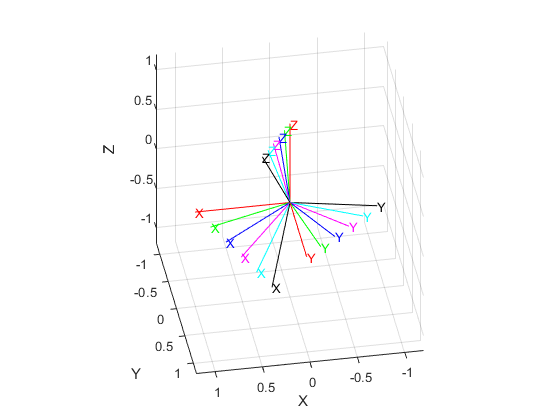

hold off

B) The absolute XYZ Euler angles can be obtained from the rotation matrix by considering the  sequence of rotations as Z-Y-X,

For the given rotation matrix, we get two sets of Euler angles,


$$\begin{array}{l}
{\theta \;}_1 {\;=28\ldotp 02\deg \;\;\psi }_1 =11\ldotp 17\deg \;\;\phi_1 =67\ldotp 8\deg \\
{\theta \;}_2 {\;=\;151\ldotp 98\deg \;\;\psi }_2 =191\ldotp 17\deg \;\;\phi_2 =247\ldotp 8\deg 
\end{array}$$


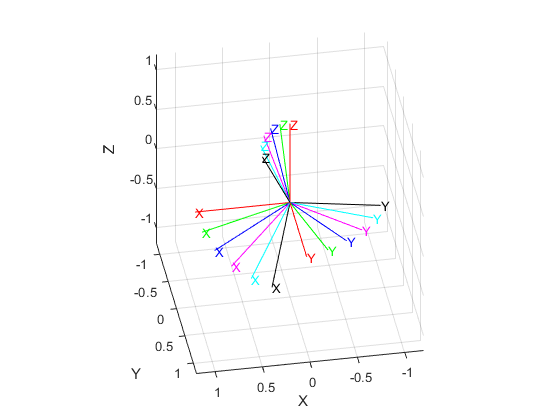

%linear interpolation between the angles
% time steps are from t=0 to t=10, in steps of 2
r_eul_int = zeros(1,3,4);
r0_eul = [0 0 0];
r10_eul = [28.02 11.17 67.8];

% interpolating the angles linearly
for i = (1:1:length(t))
    T = t(i,1);
    for j = (1:1:size(r0_eul,1))
        for k = (1:1:size(r0_eul,2))
            r_eul_int(j,k,i) = (((r10_eul(j,k)-r0_eul(j,k))/(10))*T)+r0_eul(j,k);            
        end
    end
end
r2_eul = r_eul_int(:,:,1);
r4_eul = r_eul_int(:,:,2);
r6_eul = r_eul_int(:,:,3);
r8_eul = r_eul_int(:,:,4);

% finding the corresponding rotation matrix using these angles

syms phi theta psi real

Rzphi   = [[cosd(phi) -sind(phi) 0];
           [sind(phi) cosd(phi) 0];
           [0 0 1]];
Rytheta = [[cosd(theta) 0 sind(theta)];
           [0 1 0];
           [-sind(theta) 0 cosd(theta)]];
Rxpsi   = [[1 0 0];
           [0 cosd(psi) -sind(psi)];
           [0 sind(psi) cosd(psi)]];
Rzyx    = Rzphi*Rytheta*Rxpsi;

r0_eul2rotm = double(subs(Rzyx,{theta,psi,phi},{r0_eul(1,1),r0_eul(1,2),r0_eul(1,3)}));
r2_eul2rotm = double(subs(Rzyx,{theta,psi,phi},{r2_eul(1,1),r2_eul(1,2),r2_eul(1,3)}));
r4_eul2rotm = double(subs(Rzyx,{theta,psi,phi},{r4_eul(1,1),r4_eul(1,2),r4_eul(1,3)}));
r6_eul2rotm = double(subs(Rzyx,{theta,psi,phi},{r6_eul(1,1),r6_eul(1,2),r6_eul(1,3)}));
r8_eul2rotm = double(subs(Rzyx,{theta,psi,phi},{r8_eul(1,1),r8_eul(1,2),r8_eul(1,3)}));
r10_eul2rotm= double(subs(Rzyx,{theta,psi,phi},{r10_eul(1,1),r10_eul(1,2),r10_eul(1,3)}));

figure;
view([170 35])
trplot(r0_eul2rotm,'color','r');
hold on
trplot(r2_eul2rotm,'color','g');
hold on
trplot(r4_eul2rotm,'color','b');
hold on
trplot(r6_eul2rotm,'color','m');
hold on
trplot(r8_eul2rotm,'color','c');
hold on
trplot(r10_eul2rotm,'color','k');
hold off

**Since the other set of angles also yield the same rotation matrix, the intermediate euler angles would also render the same rotation matrices.**

C) The relative XYZ Euler angles can be obtained from the rotation matrix by considering the  sequence of rotations as X-Y-Z,

For the given rotation matrix, the Euler angles obtained are,

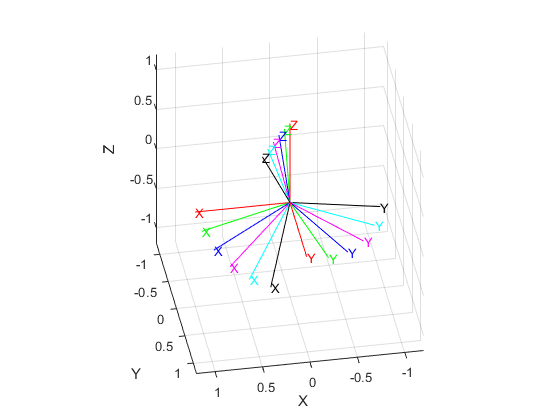

% finding the XYZ Euler angles corresponding to the two rotation matrices
r0_xyz = rotm2eul(r0,'XYZ');
r10_xyz = rotm2eul(r10,'XYZ');
r_xyz_int = zeros(1,3,4);

% interpolating the angles linearly
for i = (1:1:length(t))
    T = t(i,1);
    for j = (1:1:size(r0_xyz,1))
        for k = (1:1:size(r0_xyz,2))
            r_xyz_int(j,k,i) = (((r10_xyz(j,k)-r0_xyz(j,k))/(10))*T)+r0_xyz(j,k);            
        end
    end
end

r2_xyz = r_xyz_int(:,:,1);
r4_xyz = r_xyz_int(:,:,2);
r6_xyz = r_xyz_int(:,:,3);
r8_xyz = r_xyz_int(:,:,4);

% finding the corresponding rotation matrix using these angles
syms phi theta psi real

Rxphi   = [[1 0 0];[0 cos(phi) -sin(phi)];[0 sin(phi) cos(phi)]];
Rytheta = [[cos(theta) 0 sin(theta)];[0 1 0];[-sin(theta) 0 cos(theta)]];
Rzpsi   = [[cos(psi) -sin(psi) 0];[sin(psi) cos(psi) 0];[0 0 1]];
Rxyz    = Rxphi*Rytheta*Rzpsi;

r0_xyz2rotm = double(subs(Rxyz,{phi,theta,psi},{r0_xyz(1,1),r0_xyz(1,2),r0_xyz(1,3)}));
r2_xyz2rotm = double(subs(Rxyz,{phi,theta,psi},{r2_xyz(1,1),r2_xyz(1,2),r2_xyz(1,3)}));
r4_xyz2rotm = double(subs(Rxyz,{phi,theta,psi},{r4_xyz(1,1),r4_xyz(1,2),r4_xyz(1,3)}));
r6_xyz2rotm = double(subs(Rxyz,{phi,theta,psi},{r6_xyz(1,1),r6_xyz(1,2),r6_xyz(1,3)}));
r8_xyz2rotm = double(subs(Rxyz,{phi,theta,psi},{r8_xyz(1,1),r8_xyz(1,2),r8_xyz(1,3)}));
r10_xyz2rotm= double(subs(Rxyz,{phi,theta,psi},{r10_xyz(1,1),r10_xyz(1,2),r10_xyz(1,3)}));

figure;
view([170 35])
trplot(r0_xyz2rotm,'color','r');
hold on
trplot(r2_xyz2rotm,'color','g');
hold on
trplot(r4_xyz2rotm,'color','b');
hold on
trplot(r6_xyz2rotm,'color','m');
hold on
trplot(r8_xyz2rotm,'color','c');
hold on
trplot(r10_xyz2rotm,'color','k');
hold off

D) Axis angle representation can be found out using the function 'rotm2axang'

r0_axang = rotm2axang(r0);
r10_axang = rotm2axang(r10);
r_axang_int = zeros(1,4,4);

% interpolating the angles linearly
for i = (1:1:length(t))
    T = t(i,1);
    for j = (1:1:size(r0_axang,1))
        for k = (1:1:size(r0_axang,2))
            r_axang_int(j,k,i) = (((r10_axang(j,k)-r0_axang(j,k))/(10))*T)+r0_axang(j,k);            
        end
    end
end

r2_axang = r_axang_int(:,:,1);
r4_axang = r_axang_int(:,:,2);
r6_axang = r_axang_int(:,:,3);
r8_axang = r_axang_int(:,:,4);

%finding the corresponding rotation matrix using these axis and angles

syms kx ky kz theta real

Raxang = [[kx^2*(1-cos(theta))+cos(theta) kx*ky*(1-cos(theta))-kz*sin(theta) kx*kz*(1-cos(theta))+ky*sin(theta)];
          [kx*ky*(1-cos(theta))+kz*sin(theta) ky^2*(1-cos(theta))+cos(theta) ky*kz*(1-cos(theta))-kx*sin(theta)];
          [kx*kz*(1-cos(theta))-ky*sin(theta) ky*kz*(1-cos(theta))+kx*sin(theta) kz^2*(1-cos(theta))+cos(theta)]];

r0_axang2rotm = double(subs(Raxang,{kx,ky,kz,theta},{r0_axang(1,1),r0_axang(1,2),r0_axang(1,3),r0_axang(1,4)}));
r2_axang2rotm = double(subs(Raxang,{kx,ky,kz,theta},{r2_axang(1,1),r2_axang(1,2),r2_axang(1,3),r2_axang(1,4)}));
r4_axang2rotm = double(subs(Raxang,{kx,ky,kz,theta},{r4_axang(1,1),r4_axang(1,2),r4_axang(1,3),r4_axang(1,4)}));
r6_axang2rotm = double(subs(Raxang,{kx,ky,kz,theta},{r6_axang(1,1),r6_axang(1,2),r6_axang(1,3),r6_axang(1,4)}));
r8_axang2rotm = double(subs(Raxang,{kx,ky,kz,theta},{r8_axang(1,1),r8_axang(1,2),r8_axang(1,3),r8_axang(1,4)}));
r10_axang2rotm= double(subs(Raxang,{kx,ky,kz,theta},{r10_axang(1,1),r10_axang(1,2),r10_axang(1,3),r10_axang(1,4)}));

figure;
view([170 35])
trplot(r0_axang2rotm,'color','r');
hold on
trplot(r2_axang2rotm,'color','g');

hold on
trplot(r4_axang2rotm,'color','b');

hold on
trplot(r6_axang2rotm,'color','m');

hold on
trplot(r8_axang2rotm,'color','c');

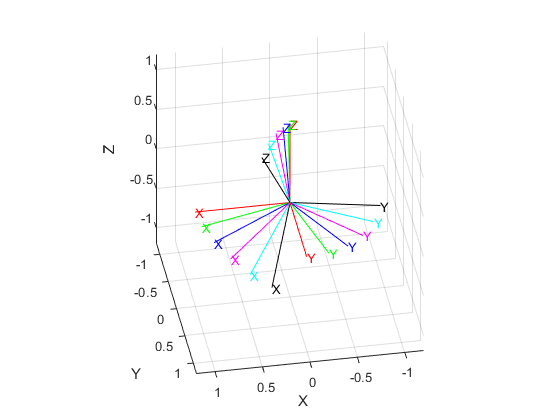

hold on
trplot(r10_axang2rotm,'color','k');
hold off

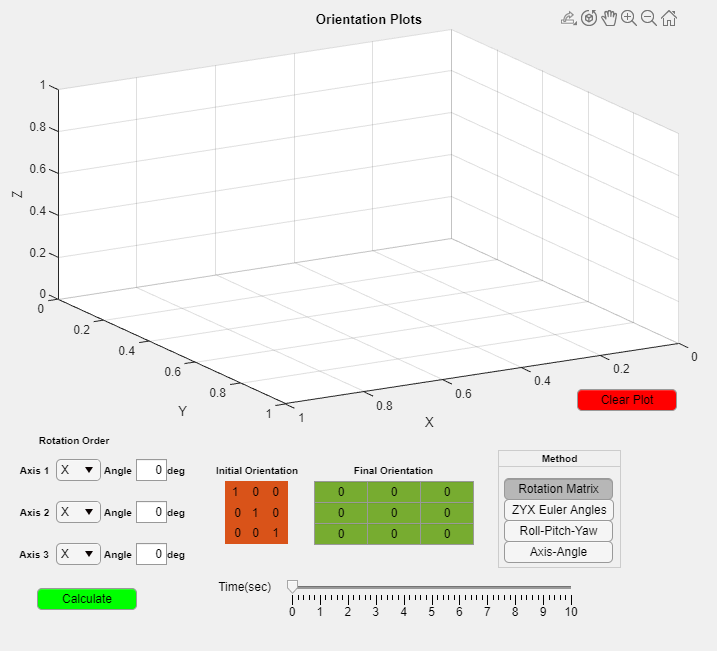

run('Q1_GUI.mlapp');

**Inputs to the GUI are as follows,**

(1) Axis of rotation for the frames

(2) Corresponding angles of rotation

(3) Method of interpolation

(4) Time in seconds, at which the position of the frame needs to be visualised

**Directions to use the GUI,**

(1) Enter the axis and angles of rotation, press calculate. This calculates the 'Final Orientation' matrix

     The initial orientation matrix is assumed to be aligned with the global frame of reference

(2) Select the method of interpolations, which essentially decides what will be interpolated

(3) Slide the 'time' slider to visualise the frames at different times

(4) Press clear plot to clear the figure, to be used when switching from one method to the other

## **PROBLEM 2**

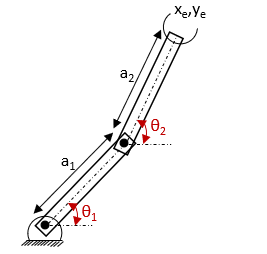

The end effector has to travel from P1 = ($x_1 ,y_1$) = (-1,1) to P2 = $\left.{\left(x\right.}_2 ,y_2 \right)$ = (2,1) in 10 seconds.

(A) **Linearly interpolated trajectory in Cartesian space:**

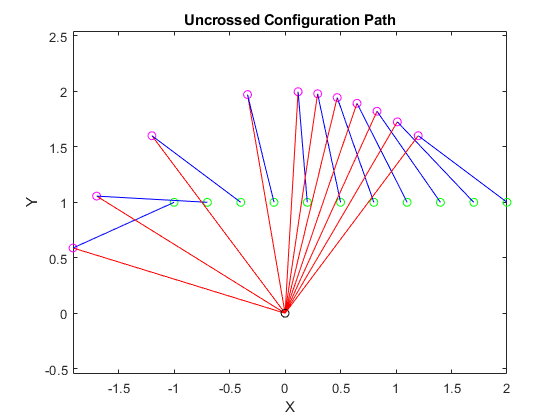

clear all;
cla reset;
p0  = [-1 1];   %position at t=0s
p10 = [2 1];    %position at t=10s
L   = [2 1];    %link-length vector
%creating the intermediate positions considering a linear trajectory
t = (1:1:9)'; %positions will be calculated every second
pe_int = zeros(1,2,length(t));  %intermediate coordinates for the end effector
for i = (1:1:length(t))
    for j = (1:1:size(p0,1))
        for k = (1:1:size(p0,2))
            pe_int(j,k,i) = (((p10(j,k) - p0(j,k))/10)*t(i,1))+(p0(j,k));
        end
    end
end
p1 = pe_int(:,:,1);
p2 = pe_int(:,:,2);
p3 = pe_int(:,:,3);
p4 = pe_int(:,:,4);
p5 = pe_int(:,:,5);
p6 = pe_int(:,:,6);
p7 = pe_int(:,:,7);
p8 = pe_int(:,:,8);
p9 = pe_int(:,:,9);
P  = [p0;p1;p2;p3;p4;p5;p6;p7;p8;p9;p10]; %vector for all the end effector positions

% calculating the theta values for these intermediate positions using the
% function 'RR_InvPosKin.m'
theta1_u = zeros(length(P),1);
theta2_u = zeros(length(P),1);
theta1_c = zeros(length(P),1);
theta2_c = zeros(length(P),1);

% uncrossed position sigma = 1
for i = (1:1:length(P))
    [theta1_u(i,1),theta2_u(i,1)] = invkinema(L,P(i,1),P(i,2),1);
end

% crossed position sigma = -1
for i = (1:1:length(P))
    [theta1_c(i,1),theta2_c(i,1)] = invkinema(L,P(i,1),P(i,2),-1);
end

% vector for all positions of joint 2
Pu_j2 = [L(1).*cosd(theta1_u) L(1).*sind(theta1_u)]; %uncrossed configuration
Pc_j2 = [L(1).*cosd(theta1_c) L(1).*sind(theta1_c)]; %crossed configuration

%plotting the results
figure(1);  %uncrossed path
for i = (1:1:length(P))
    plot(0,0,'ko');
    axis equal
    hold on
    plot(Pu_j2(i,1),Pu_j2(i,2),'mo');
    hold on
    plot(P(i,1),P(i,2),'go');
    hold on
    plot([0,Pu_j2(i,1)],[0,Pu_j2(i,2)],'r-');   %first link positions
    hold on
    plot([Pu_j2(i,1),P(i,1)],[Pu_j2(i,2),P(i,2)],'b-')  %second link positions
    title('Uncrossed Configuration Path');
    xlabel('X');
    ylabel('Y');
end

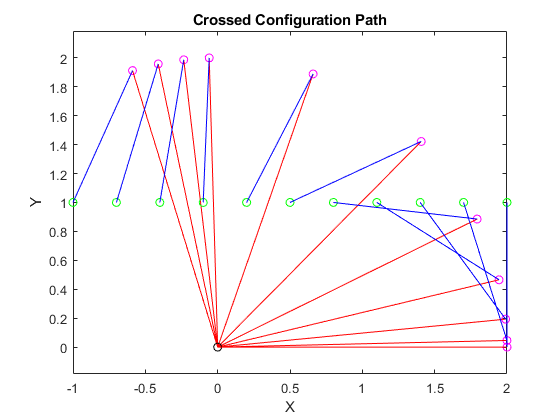

figure(2);  %crossed path
for i = (1:1:length(P))
    plot(0,0,'ko');
    axis equal
    hold on
    plot(Pc_j2(i,1),Pc_j2(i,2),'mo');
    hold on
    plot(P(i,1),P(i,2),'go');
    hold on
    plot([0,Pc_j2(i,1)],[0,Pc_j2(i,2)],'r-');   %first link positions
    hold on
    plot([Pc_j2(i,1),P(i,1)],[Pc_j2(i,2),P(i,2)],'b-')  %second link positions
    title('Crossed Configuration Path');
    xlabel('X');
    ylabel('Y');
end

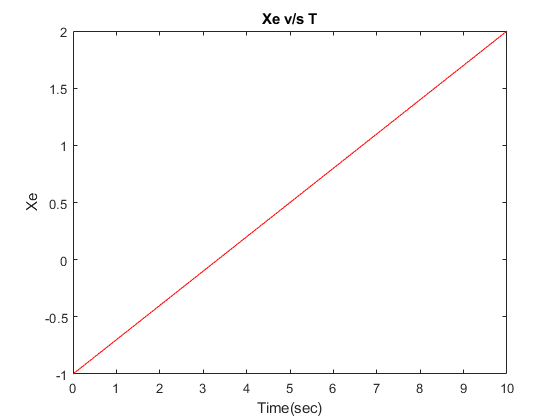

%(Ai) Xe v/s t
figure(3);
T = (0:1:10)';
plot(T,P(:,1),'r-')
title('Xe v/s T');
xlabel('Time(sec)');
ylabel('Xe');

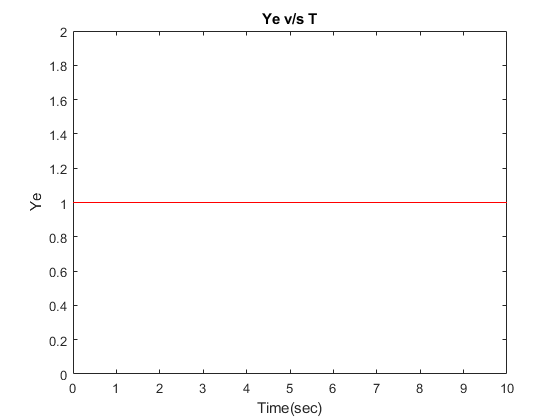

%(Aii) Ye v/s t
figure(4);
plot(T,P(:,2),'r-')
title('Ye v/s T');
xlabel('Time(sec)');
ylabel('Ye');

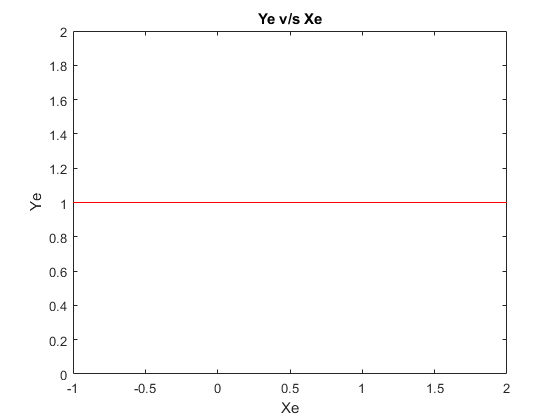

%(Aiii) Ye v/s Xe
figure(5);
plot(P(:,1),P(:,2),'r-')
title('Ye v/s Xe');
xlabel('Xe');
ylabel('Ye');

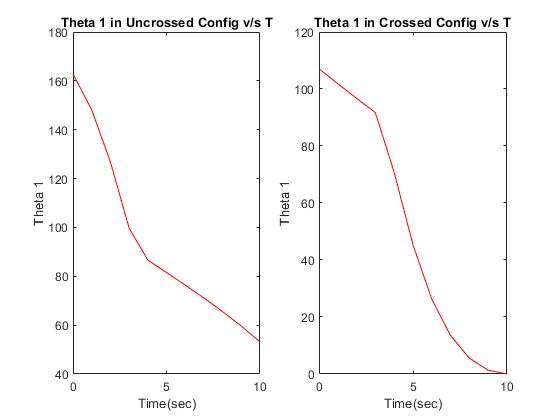

%(Aiv) theta 1 v/s t in crossed and uncrossed condition
figure(6);
subplot(1,2,1)
plot(T,theta1_u,'r-')
title('Theta 1 in Uncrossed Config v/s T');
xlabel('Time(sec)');
ylabel('Theta 1');
subplot(1,2,2)
plot(T,theta1_c,'r-')
title('Theta 1 in Crossed Config v/s T');
xlabel('Time(sec)');
ylabel('Theta 1');

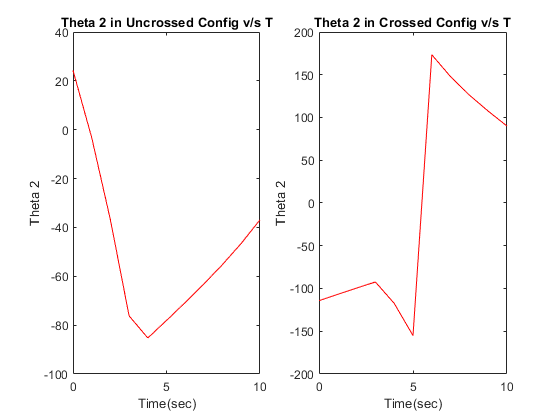

%(Av) theta 2 v/s t in crossed and uncrossed condition
figure(7);
subplot(1,2,1)
plot(T,theta2_u,'r-')
title('Theta 2 in Uncrossed Config v/s T');
xlabel('Time(sec)');
ylabel('Theta 2');
subplot(1,2,2)
plot(T,theta2_c,'r-')
title('Theta 2 in Crossed Config v/s T');
xlabel('Time(sec)');
ylabel('Theta 2');

(B) **Linearly interpolated trajectory in joint space:** 

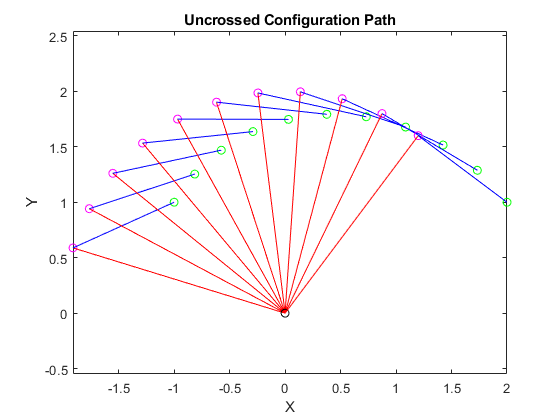

clear all;
p0  = [-1 1];   %position at t=0s
p10 = [2 1];    %position at t=10s
L   = [2 1];    %link-length vector

%calculating the joint 2 coordinates using the function 'RR_InvPosKin.m'
%corresponding to p0 and p10

[theta1_u0,theta2_u0] = invkinema(L,p0(1,1),p0(1,2),1);      %theta values at t=0,  uncrossed
[theta1_u10,theta2_u10] = invkinema(L,p10(1,1),p10(1,2),1);  %theta values at t=10, uncrossed
[theta1_c0,theta2_c0] = invkinema(L,p0(1,1),p0(1,2),-1);     %theta values at t=0, crossed
[theta1_c10,theta2_c10] = invkinema(L,p10(1,1),p10(1,2),-1); %theta values at t=10, crossed

%% uncrossed configuration
t = (1:1:9)';
theta1_uint = zeros(1,1,length(t));  %3D matrix to store the interim theta1(uncrossed)
theta2_uint = zeros(1,1,length(t));  %3D matrix to store the interim theta2(uncrossed)

for i = (1:1:length(t))
    theta1_uint(1,1,i) = (((theta1_u10-theta1_u0)/10)*t(i,1))+theta1_u0;
    theta2_uint(1,1,i) = (((theta2_u10-theta2_u0)/10)*t(i,1))+theta2_u0;
end

theta1_u1 = theta1_uint(1,1,1);
theta1_u2 = theta1_uint(1,1,2);
theta1_u3 = theta1_uint(1,1,3);
theta1_u4 = theta1_uint(1,1,4);
theta1_u5 = theta1_uint(1,1,5);
theta1_u6 = theta1_uint(1,1,6);
theta1_u7 = theta1_uint(1,1,7);
theta1_u8 = theta1_uint(1,1,8);
theta1_u9 = theta1_uint(1,1,9);
theta1_u = [theta1_u0;theta1_u1;theta1_u2;theta1_u3;theta1_u4;theta1_u5;theta1_u6;theta1_u7;theta1_u8;theta1_u9;theta1_u10];

theta2_u1 = theta2_uint(1,1,1);
theta2_u2 = theta2_uint(1,1,2);
theta2_u3 = theta2_uint(1,1,3);
theta2_u4 = theta2_uint(1,1,4);
theta2_u5 = theta2_uint(1,1,5);
theta2_u6 = theta2_uint(1,1,6);
theta2_u7 = theta2_uint(1,1,7);
theta2_u8 = theta2_uint(1,1,8);
theta2_u9 = theta2_uint(1,1,9);
theta2_u = [theta2_u0;theta2_u1;theta2_u2;theta2_u3;theta2_u4;theta2_u5;theta2_u6;theta2_u7;theta2_u8;theta2_u9;theta2_u10];

%coordinates of joint 2 and end effector (uncrossed)
j2_u = zeros(length(theta1_u),2); %initialize a 2D matrix to store all the joint 2 coordinates (uncrossed)
ee_u = zeros(length(theta1_u),2); %initialize a 2D matrix to store all the end effector coordinates (uncrossed)
for i = (1:1:length(theta1_u))
    j2_u(i,1) = L(1)*cosd(theta1_u(i,1));
    j2_u(i,2) = L(1)*sind(theta1_u(i,1));
    ee_u(i,1) = L(1)*cosd(theta1_u(i,1)) + L(2)*cosd(theta2_u(i,1));
    ee_u(i,2) = L(1)*sind(theta1_u(i,1)) + L(2)*sind(theta2_u(i,1));
end

%% crossed configuration
theta1_cint = zeros(1,1,length(t));  %3D matrix to store the interim theta1(crossed)
theta2_cint = zeros(1,1,length(t));  %3D matrix to store the interim theta2(crossed)

for i = (1:1:length(t))
    theta1_cint(1,1,i) = (((theta1_c10-theta1_c0)/10)*t(i,1))+theta1_c0;
    theta2_cint(1,1,i) = (((theta2_c10-theta2_c0)/10)*t(i,1))+theta2_c0;
end

theta1_c1 = theta1_cint(1,1,1);
theta1_c2 = theta1_cint(1,1,2);
theta1_c3 = theta1_cint(1,1,3);
theta1_c4 = theta1_cint(1,1,4);
theta1_c5 = theta1_cint(1,1,5);
theta1_c6 = theta1_cint(1,1,6);
theta1_c7 = theta1_cint(1,1,7);
theta1_c8 = theta1_cint(1,1,8);
theta1_c9 = theta1_cint(1,1,9);
theta1_c = [theta1_c0;theta1_c1;theta1_c2;theta1_c3;theta1_c4;theta1_c5;theta1_c6;theta1_c7;theta1_c8;theta1_c9;theta1_c10];

theta2_c1 = theta2_cint(1,1,1);
theta2_c2 = theta2_cint(1,1,2);
theta2_c3 = theta2_cint(1,1,3);
theta2_c4 = theta2_cint(1,1,4);
theta2_c5 = theta2_cint(1,1,5);
theta2_c6 = theta2_cint(1,1,6);
theta2_c7 = theta2_cint(1,1,7);
theta2_c8 = theta2_cint(1,1,8);
theta2_c9 = theta2_cint(1,1,9);
theta2_c = [theta2_c0;theta2_c1;theta2_c2;theta2_c3;theta2_c4;theta2_c5;theta2_c6;theta2_c7;theta2_c8;theta2_c9;theta2_c10];

%coordinates of joint 2 and end effector (uncrossed)
j2_c = zeros(length(theta1_c),2); %initialize a 2D matrix to store all the joint 2 coordinates (uncrossed)
ee_c = zeros(length(theta1_c),2); %initialize a 2D matrix to store all the end effector coordinates (uncrossed)
for i = (1:1:length(theta1_c))
    j2_c(i,1) = L(1)*cosd(theta1_c(i,1));
    j2_c(i,2) = L(1)*sind(theta1_c(i,1));
    ee_c(i,1) = L(1)*cosd(theta1_c(i,1)) + L(2)*cosd(theta2_c(i,1));
    ee_c(i,2) = L(1)*sind(theta1_c(i,1)) + L(2)*sind(theta2_c(i,1));
end

%plotting the results
figure(8);  %uncrossed path
for i = (1:1:length(ee_u))
    plot(0,0,'ko');
    axis equal
    hold on
    plot(j2_u(i,1),j2_u(i,2),'mo');
    hold on
    plot(ee_u(i,1),ee_u(i,2),'go');
    hold on
    plot([0,j2_u(i,1)],[0,j2_u(i,2)],'r-');   %first link positions
    hold on
    plot([j2_u(i,1),ee_u(i,1)],[j2_u(i,2),ee_u(i,2)],'b-')  %second link positions
    title('Uncrossed Configuration Path');
    xlabel('X');
    ylabel('Y');
end

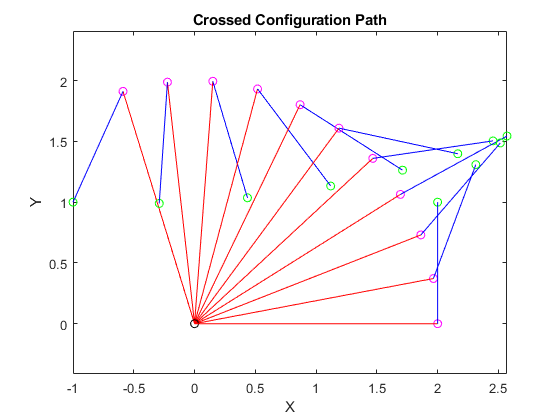

figure(9);  %crossed path
for i = (1:1:length(ee_c))
    plot(0,0,'ko');
    axis equal
    hold on
    plot(j2_c(i,1),j2_c(i,2),'mo');
    hold on
    plot(ee_c(i,1),ee_c(i,2),'go');
    hold on
    plot([0,j2_c(i,1)],[0,j2_c(i,2)],'r-');   %first link positions
    hold on
    plot([j2_c(i,1),ee_c(i,1)],[j2_c(i,2),ee_c(i,2)],'b-')  %second link positions
    title('Crossed Configuration Path');
    xlabel('X');
    ylabel('Y');
end

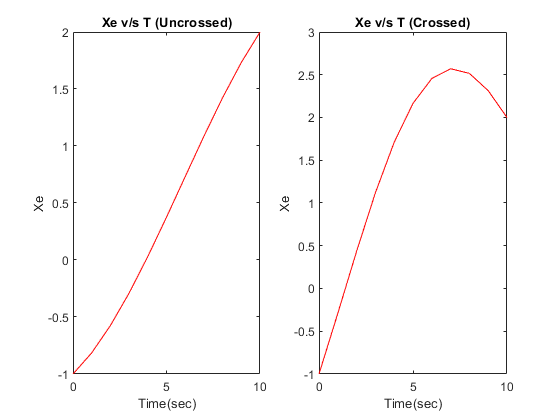

%(Bi) Xe v/s t
figure(10);
T = (0:1:10)';
subplot(1,2,1)
plot(T,ee_u(:,1),'r-')
title('Xe v/s T (Uncrossed)');
xlabel('Time(sec)');
ylabel('Xe');
subplot(1,2,2)
plot(T,ee_c(:,1),'r-')
title('Xe v/s T (Crossed)');
xlabel('Time(sec)');
ylabel('Xe');

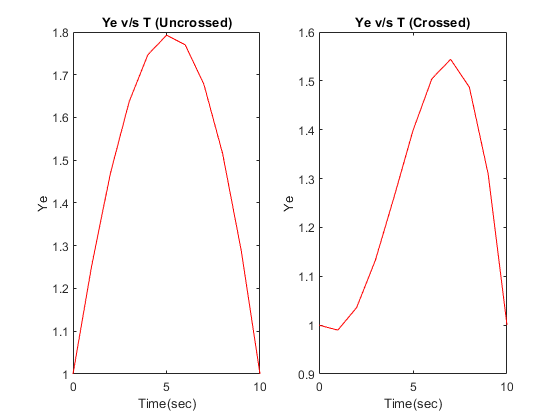

%(Bii) Ye v/s t
figure(11);
T = (0:1:10)';
subplot(1,2,1)
plot(T,ee_u(:,2),'r-')
title('Ye v/s T (Uncrossed)');
xlabel('Time(sec)');
ylabel('Ye');
subplot(1,2,2)
plot(T,ee_c(:,2),'r-')
title('Ye v/s T (Crossed)');
xlabel('Time(sec)');
ylabel('Ye');

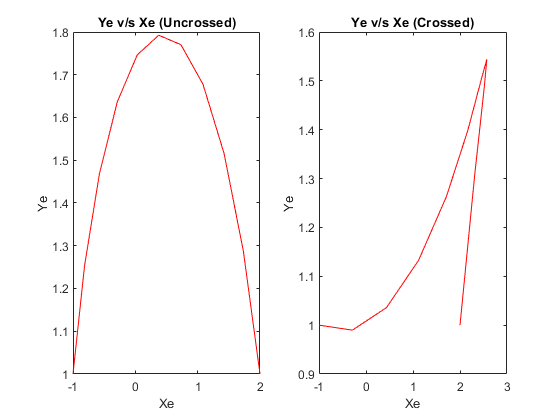

%(Biii) Ye v/s Xe
figure(12);
T = (0:1:10)';
subplot(1,2,1)
plot(ee_u(:,1),ee_u(:,2),'r-')
title('Ye v/s Xe (Uncrossed)');
xlabel('Xe');
ylabel('Ye');
subplot(1,2,2)
plot(ee_c(:,1),ee_c(:,2),'r-')
title('Ye v/s Xe (Crossed)');
xlabel('Xe');
ylabel('Ye');

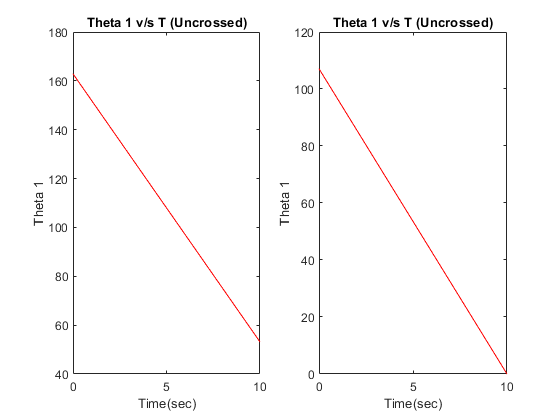

%(Biv) theta 1 v/s t in crossed and uncrossed condition
figure(13);
subplot(1,2,1)
plot(T,theta1_u,'r-')
title('Theta 1 v/s T (Uncrossed)');
xlabel('Time(sec)');
ylabel('Theta 1');
subplot(1,2,2)
plot(T,theta1_c,'r-')
title('Theta 1 v/s T (Crossed)');
xlabel('Time(sec)');
ylabel('Theta 1');

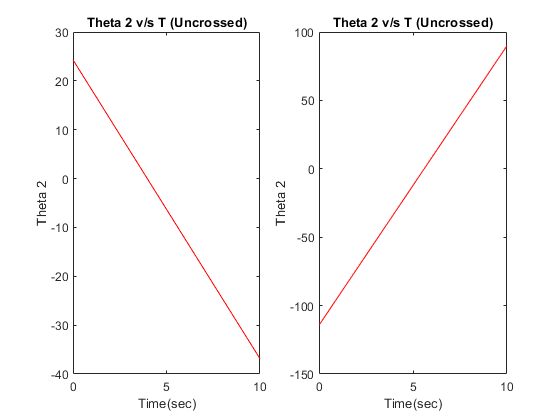

%(Biv) theta 2 v/s t in crossed and uncrossed condition
figure(14);
subplot(1,2,1)
plot(T,theta2_u,'r-')
title('Theta 2 v/s T (Uncrossed)');
xlabel('Time(sec)');
ylabel('Theta 2');
subplot(1,2,2)
plot(T,theta2_c,'r-')
title('Theta 2 v/s T (Crossed)');
xlabel('Time(sec)');
ylabel('Theta 2');

(C) **Manipulator starts from rest and stops at rest, trajectory described by a quintic polynomial in cartesian coordinates**

The equations of motion of this system can be given as,


$$\begin{array}{l}
Y_e \left(t\right)={{\mathrm{a}}_y t}^5 +{{\mathrm{b}}_y t}^4 +{{\mathrm{c}}_y t}^3 +{{\mathrm{d}}_y t}^2 +{\mathrm{e}}_y t+f_y \\
X_e \left(t\right)={{\mathrm{a}}_x t}^5 +{{\mathrm{b}}_x t}^4 +{{\mathrm{c}}_x t}^3 +{{\mathrm{d}}_x t}^2 +{\mathrm{e}}_x t+f_x 
\end{array}$$


First considering the equation of $Y_e \left(t\right),$ we have 6 equations and following are the 6 equations needed to find the coeffecients,

(i) $Y_e \left(t=0\right)=f_y =1$

(ii) $Y_e \left(t=10\right)=$${{\mathrm{a}}_y 10}^5 +{{\mathrm{b}}_y 10}^4 +{{\mathrm{c}}_y 10}^3 +{{\mathrm{d}}_y 10}^2 +{\mathrm{e}}_y 10+f_y =1$

(iii) ${\dot{Y} }_e \left(t=0\right)=5a_y t^4 +4b_y t^3 +3c_y t^2 +2d_y t +e_y =e_y =0$

(iv) ${\dot{Y} }_e \left(t=10\right)=5a_y {10}^4 +4b_y {10}^3 +3c_y {10}^2 +20d_y +e_y =0$

(v)${\ddot{Y} }_e \left(t=0\right)=20a_y t^3 +12b_y t^2 +6c_y t +2d_y =d_y =0$

(vi)${\ddot{Y} }_e \left(t=10\right)=20a_y {10}^3 +12b_y {10}^2 +6{0c}_y +2d_y =0$

Constructing these set of equations in matrix form we get,


$$\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 0 & 0 & 1\\
{10}^5  & {10}^4  & {10}^3  & {10}^2  & 10 & 1\\
0 & 0 & 0 & 0 & 1 & 0\\
5*{10}^4  & 4*{10}^3  & 3*{10}^2  & 20 & 1 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
20*{10}^3  & 12*{10}^2  & 60 & 2 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_y \\
b_y \\
c_y \\
d_y \\
e_y \\
f_y 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
1\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


clear all
%%solving for these system of equations
AY = [[0 0 0 0 0 1];
     [10^5 10^4 10^3 10^2 10 1];
     [0 0 0 0 1 0];
     [5*10^4 4*10^3 3*10^2 20 1 0];
     [0 0 0 1 0 0];
     [20*10^3 12*10^2 60 2 0 0]];
BY = [1;1;0;0;0;0];
Y = AY\BY;

Similarly considering the equation of $X_e \left(t\right),$ we have 6 equations and following are the 6 equations needed to find the coeffecients,

(i) $X_e \left(t=0\right)=f_x =-1$

(ii) $X_e \left(t=10\right)=$${{\mathrm{a}}_x 10}^5 +{{\mathrm{b}}_x 10}^4 +{{\mathrm{c}}_x 10}^3 +{{\mathrm{d}}_x 10}^2 +{\mathrm{e}}_x 10+f_x =2$

(iii) ${\dot{X} }_e \left(t=0\right)=5a_x t^4 +4b_x t^3 +3c_x t^2 +2d_x t +e_x =e_x =0$

(iv) ${\dot{X} }_e \left(t=10\right)=5a_x {10}^4 +4b_x {10}^3 +3c_x {10}^2 +20d_x +e_x =0$

(v)${\ddot{X} }_e \left(t=0\right)=20a_x t^3 +12b_x t^2 +6c_x t +2d_x =d_x =0$

(vi)${\ddot{X} }_e \left(t=10\right)=20a_x {10}^3 +12b_x {10}^2 +6{0c}_x +2d_x =0$

Constructing these set of equations in matrix form we get,


$$\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 0 & 0 & 1\\
{10}^5  & {10}^4  & {10}^3  & {10}^2  & 10 & 1\\
0 & 0 & 0 & 0 & 1 & 0\\
5*{10}^4  & 4*{10}^3  & 3*{10}^2  & 20 & 1 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
20*{10}^3  & 12*{10}^2  & 60 & 2 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_x \\
b_x \\
c_x \\
d_x \\
e_x \\
f_x 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-1\\
2\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


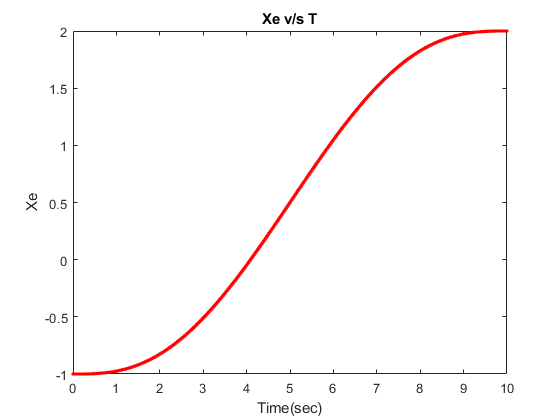

%%solving for these system of equations
AX = [[0 0 0 0 0 1];
     [10^5 10^4 10^3 10^2 10 1];
     [0 0 0 0 1 0];
     [5*10^4 4*10^3 3*10^2 20 1 0];
     [0 0 0 1 0 0];
     [20*10^3 12*10^2 60 2 0 0]];
BX = [-1;2;0;0;0;0];
X = AX\BX;

%using the quintic equations to estimate the position
t = (0:0.01:10)';
L = [2 1];
Xe = zeros(length(t),1);
Ye = zeros(length(t),1);
for i = (1:1:length(t))
    Xe(i,1) = X(1,1)*(t(i,1))^5+X(2,1)*(t(i,1))^4+X(3,1)*(t(i,1))^3+X(4,1)*(t(i,1))^2+X(5,1)*(t(i,1))+X(6,1);
    Ye(i,1) = Y(1,1)*(t(i,1))^5+Y(2,1)*(t(i,1))^4+Y(3,1)*(t(i,1))^3+Y(4,1)*(t(i,1))^2+Y(5,1)*(t(i,1))+Y(6,1);
end

%finding the theta1 and theta2 values at these end effector positions
theta1_u = zeros(length(t),1);
theta1_c = zeros(length(t),1);
theta2_u = zeros(length(t),1);
theta2_c = zeros(length(t),1);

[theta1_u,theta2_u] = invkinema(L,Xe,Ye,1);
[theta1_c,theta2_c] = invkinema(L,Xe,Ye,-1);

%plotting the results

%(Ci) Xe v/s t
figure(15);
plot(t,Xe,'r.')
title('Xe v/s T');
xlabel('Time(sec)');
ylabel('Xe');

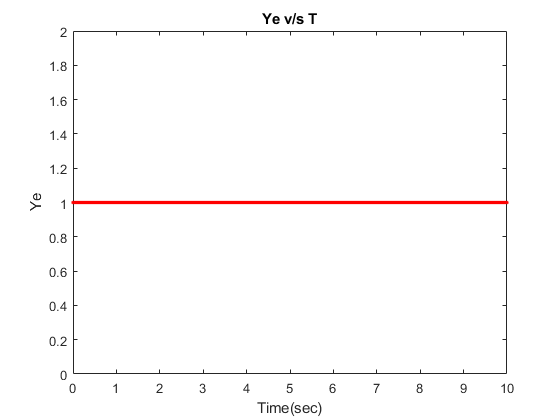

%(Cii) Ye v/s t
figure(16);
plot(t,Ye,'r.')
title('Ye v/s T');
xlabel('Time(sec)');
ylabel('Ye');

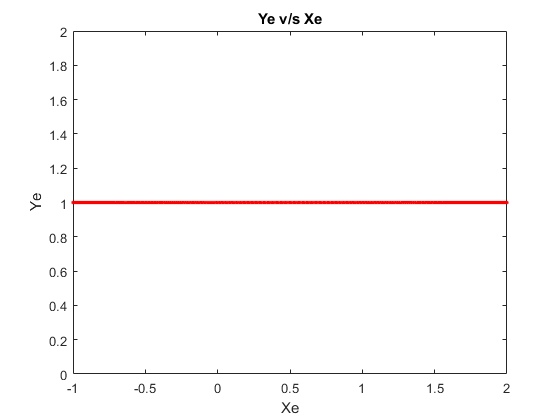

%(Ciii) Ye v/s Xe
figure(17);
plot(Xe,Ye,'r.')
title('Ye v/s Xe');
xlabel('Xe');
ylabel('Ye');

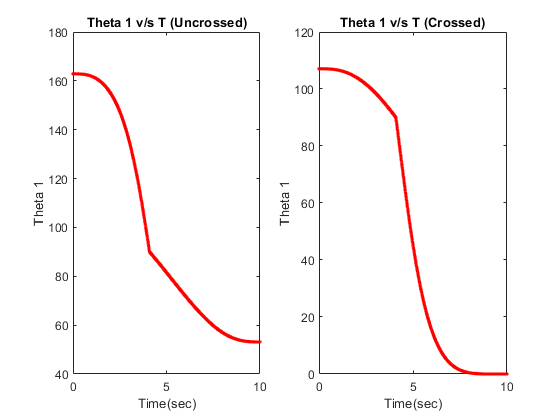

%(Civ) theta 1 v/s t in crossed and uncrossed condition
figure(18);
subplot(1,2,1)
plot(t,theta1_u,'r.')
title('Theta 1 v/s T (Uncrossed)');
xlabel('Time(sec)');
ylabel('Theta 1');
subplot(1,2,2)
plot(t,theta1_c,'r.')
title('Theta 1 v/s T (Crossed)');
xlabel('Time(sec)');
ylabel('Theta 1');

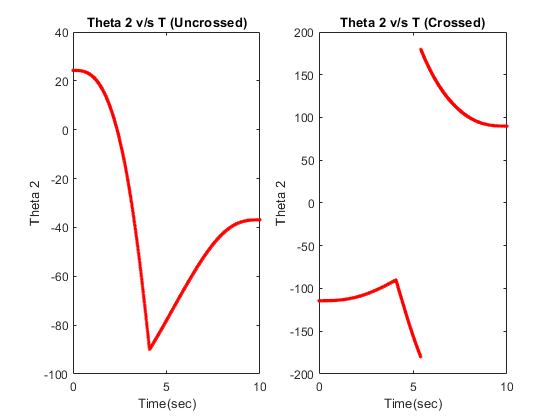

%(Biv) theta 2 v/s t in crossed and uncrossed condition
figure(19);
subplot(1,2,1)
plot(t,theta2_u,'r.')
title('Theta 2 v/s T (Uncrossed)');
xlabel('Time(sec)');
ylabel('Theta 2');
subplot(1,2,2)
plot(t,theta2_c,'r.')
title('Theta 2 v/s T (Crossed)');
xlabel('Time(sec)');
ylabel('Theta 2');

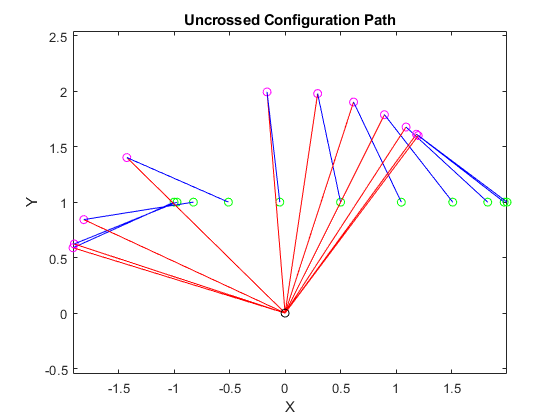

%% tracing the movement of the linkages

%uncrossed configuration
J2_ux = L(1)*cosd(theta1_u);
J2_uy = L(1)*sind(theta1_u);
j2_u = [J2_ux J2_uy];
figure(20);  %uncrossed path
for i = (1:100:length(J2_ux))
    plot(0,0,'ko');
    axis equal
    hold on
    plot(j2_u(i,1),j2_u(i,2),'mo');
    hold on
    plot(Xe(i,1),Ye(i,1),'go');
    hold on
    plot([0,j2_u(i,1)],[0,j2_u(i,2)],'r-');   %first link positions
    hold on
    plot([j2_u(i,1),Xe(i,1)],[j2_u(i,2),Ye(i,1)],'b-')  %second link positions
    title('Uncrossed Configuration Path');
    xlabel('X');
    ylabel('Y');
end

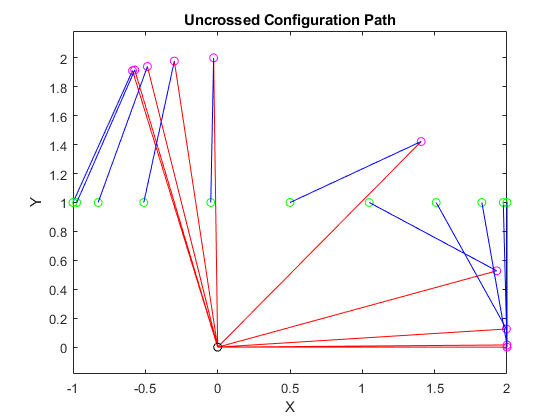

%crossed configuration
J2_cx = L(1)*cosd(theta1_c);
J2_cy = L(1)*sind(theta1_c);
j2_c = [J2_cx J2_cy];
figure(21);  %crossed path
for i = (1:100:length(J2_cx))
    plot(0,0,'ko');
    axis equal
    hold on
    plot(j2_c(i,1),j2_c(i,2),'mo');
    hold on
    plot(Xe(i,1),Ye(i,1),'go');
    hold on
    plot([0,j2_c(i,1)],[0,j2_c(i,2)],'r-');   %first link positions
    hold on
    plot([j2_c(i,1),Xe(i,1)],[j2_c(i,2),Ye(i,1)],'b-')  %second link positions
    title('Crossed Configuration Path');
    xlabel('X');
    ylabel('Y');
end

(C) **Manipulator starts from rest and stops at rest, trajectory described by a quintic polynomial in joint coordinates**

The equations of motion of this system can be given as,


$$\begin{array}{l}
\theta_1 \left(t\right)={{\mathrm{a}}_1 t}^5 +{{\mathrm{b}}_1 t}^4 +{{\mathrm{c}}_1 t}^3 +{{\mathrm{d}}_1 t}^2 +{\mathrm{e}}_1 t+f_1 \\
\theta_2 \left(t\right)={{\mathrm{a}}_2 t}^5 +{{\mathrm{b}}_2 t}^4 +{{\mathrm{c}}_2 t}^3 +{{\mathrm{d}}_2 t}^2 +{\mathrm{e}}_2 t+f_2 
\end{array}$$


First considering the equation of $\theta_1 \left(t\right),$ we have 6 equations and following are the 6 equations needed to find the coeffecients,

(i) $\theta_1 \left(t=0\right)=f_1 =\mathrm{theta1}\;@\;t=0\;\left(\mathrm{obtained}\;\mathrm{using}\;\mathrm{the}\;\mathrm{invkinema}\;\mathrm{function}\right)$

(ii) $\theta_1 \left(t=10\right)=$${{\mathrm{a}}_1 10}^5 +{{\mathrm{b}}_1 10}^4 +{{\mathrm{c}}_1 10}^3 +{{\mathrm{d}}_1 10}^2 +{\mathrm{e}}_1 10+f_1 =\mathrm{theta1}\;@\;t=10\;\left(\mathrm{obtained}\;\mathrm{using}\;\mathrm{invkinema}\;\mathrm{function}\right)$

(iii) ${\dot{\theta} }_1 \left(t=0\right)=5a_1 t^4 +4b_1 t^3 +3c_1 t^2 +2d_1 t +e_1 =e_1 =0$

(iv) ${\dot{\theta} }_1 \left(t=10\right)=5a_1 {10}^4 +4b_1 {10}^3 +3c_1 {10}^2 +20d_1 +e_1 =0$

(v)${\ddot{\theta} }_1 \left(t=0\right)=20a_1 t^3 +12b_1 t^2 +6c_1 t +2d_1 =d_1 =0$

(vi)${\ddot{\theta} }_1 \left(t=10\right)=20a_1 {10}^3 +12b_1 {10}^2 +6{0c}_1 +2d_1 =0$

clear all
%obtaining the values of theta1 & theta2 @ crossed and uncrossed conditions
p0  = [-1 1];
p10 = [2 1];
L = [2 1];
[theta1_u0,theta2_u0] = invkinema(L,p0(1),p0(2),1);
[theta1_c0,theta2_c0] = invkinema(L,p0(1),p0(2),-1);
[theta1_u10,theta2_u10] = invkinema(L,p10(1),p10(2),1);
[theta1_c10,theta2_c10] = invkinema(L,p10(1),p10(2),-1);

Constructing these set of equations for the uncrossed configuration in matrix form we get,


$$\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 0 & 0 & 1\\
{10}^5  & {10}^4  & {10}^3  & {10}^2  & 10 & 1\\
0 & 0 & 0 & 0 & 1 & 0\\
5*{10}^4  & 4*{10}^3  & 3*{10}^2  & 20 & 1 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
20*{10}^3  & 12*{10}^2  & 60 & 2 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_{1u} \\
b_{1u} \\
c_{1u} \\
d_{1u} \\
e_{1u} \\
f_{1u} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\mathrm{theta1}\_\mathrm{u0}\\
\mathrm{theta1}\_\mathrm{u10}\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


Similarly for the crossed configuration,


$$\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 0 & 0 & 1\\
{10}^5  & {10}^4  & {10}^3  & {10}^2  & 10 & 1\\
0 & 0 & 0 & 0 & 1 & 0\\
5*{10}^4  & 4*{10}^3  & 3*{10}^2  & 20 & 1 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
20*{10}^3  & 12*{10}^2  & 60 & 2 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_{1c} \\
b_{1c} \\
c_{1c} \\
d_{1c} \\
e_{1c} \\
f_{1c} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\mathrm{theta1}\_\mathrm{c0}\\
\mathrm{theta1}\_\mathrm{c10}\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


The theta 2 equations for the two configurations would be,


$$\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 0 & 0 & 1\\
{10}^5  & {10}^4  & {10}^3  & {10}^2  & 10 & 1\\
0 & 0 & 0 & 0 & 1 & 0\\
5*{10}^4  & 4*{10}^3  & 3*{10}^2  & 20 & 1 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
20*{10}^3  & 12*{10}^2  & 60 & 2 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_{2u} \\
b_{2u} \\
c_{2u} \\
d_{2u} \\
e_{2u} \\
f_{2u} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\mathrm{theta2}\_\mathrm{u0}\\
\mathrm{theta2}\_\mathrm{u10}\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 0 & 0 & 1\\
{10}^5  & {10}^4  & {10}^3  & {10}^2  & 10 & 1\\
0 & 0 & 0 & 0 & 1 & 0\\
5*{10}^4  & 4*{10}^3  & 3*{10}^2  & 20 & 1 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
20*{10}^3  & 12*{10}^2  & 60 & 2 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_{2c} \\
b_{2c} \\
c_{2c} \\
d_{2c} \\
e_{2c} \\
f_{2c} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\mathrm{theta2}\_\mathrm{c0}\\
\mathrm{theta2}\_\mathrm{c10}\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


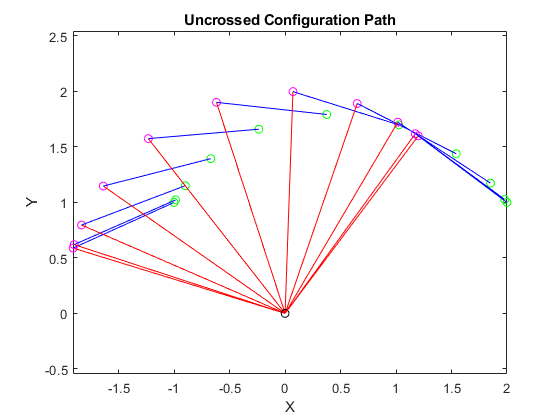

% solving the system of equations for all the 4 conditions,
%uncrossed theta1
A = [[0 0 0 0 0 1];
     [10^5 10^4 10^3 10^2 10 1];
     [0 0 0 0 1 0];
     [5*10^4 4*10^3 3*10^2 20 1 0];
     [0 0 0 1 0 0];
     [20*10^3 12*10^2 60 2 0 0]];
B_theta1_u = [theta1_u0;theta1_u10;0;0;0;0];
B_theta1_c = [theta1_c0;theta1_c10;0;0;0;0];
B_theta2_u = [theta2_u0;theta2_u10;0;0;0;0];
B_theta2_c = [theta2_c0;theta2_c10;0;0;0;0];

%coeffecients
C_theta1_u = A\B_theta1_u;
C_theta1_c = A\B_theta1_c;
C_theta2_u = A\B_theta2_u;
C_theta2_c = A\B_theta2_c;

%theta values at different instants
t = (0:0.01:10)';

for i = (1:1:length(t))
    theta1_u(i,1) = C_theta1_u(1,1)*(t(i,1))^5+C_theta1_u(2,1)*(t(i,1))^4+C_theta1_u(3,1)*(t(i,1))^3+C_theta1_u(4,1)*(t(i,1))^2+C_theta1_u(5,1)*(t(i,1))+C_theta1_u(6,1);
    theta1_c(i,1) = C_theta1_c(1,1)*(t(i,1))^5+C_theta1_c(2,1)*(t(i,1))^4+C_theta1_c(3,1)*(t(i,1))^3+C_theta1_c(4,1)*(t(i,1))^2+C_theta1_c(5,1)*(t(i,1))+C_theta1_c(6,1);
    theta2_u(i,1) = C_theta2_u(1,1)*(t(i,1))^5+C_theta2_u(2,1)*(t(i,1))^4+C_theta2_u(3,1)*(t(i,1))^3+C_theta2_u(4,1)*(t(i,1))^2+C_theta2_u(5,1)*(t(i,1))+C_theta2_u(6,1);
    theta2_c(i,1) = C_theta2_c(1,1)*(t(i,1))^5+C_theta2_c(2,1)*(t(i,1))^4+C_theta2_c(3,1)*(t(i,1))^3+C_theta2_c(4,1)*(t(i,1))^2+C_theta2_c(5,1)*(t(i,1))+C_theta2_c(6,1);
end

%uncrossed joint and end effector coordinates
J2_xu = L(1)*cosd(theta1_u);
J2_yu = L(1)*sind(theta1_u);
ee_xu = L(1)*cosd(theta1_u) + L(2)*cosd(theta2_u);
ee_yu = L(1)*sind(theta1_u) + L(2)*sind(theta2_u);

%crossed joint and end effector coordinates
J2_xc = L(1)*cosd(theta1_c);
J2_yc = L(1)*sind(theta1_c);
ee_xc = L(1)*cosd(theta1_c) + L(2)*cosd(theta2_c);
ee_yc = L(1)*sind(theta1_c) + L(2)*sind(theta2_c);

%%plotting the results
figure(22);  %uncrossed path
for i = (1:100:length(J2_xu))
    plot(0,0,'ko');
    axis equal
    hold on
    plot(J2_xu(i,1),J2_yu(i,1),'mo');
    hold on
    plot(ee_xu(i,1),ee_yu(i,1),'go');
    hold on
    plot([0,J2_xu(i,1)],[0,J2_yu(i,1)],'r-');   %first link positions
    hold on
    plot([J2_xu(i,1),ee_xu(i,1)],[J2_yu(i,1),ee_yu(i,1)],'b-')  %second link positions
    title('Uncrossed Configuration Path');
    xlabel('X');
    ylabel('Y');
end

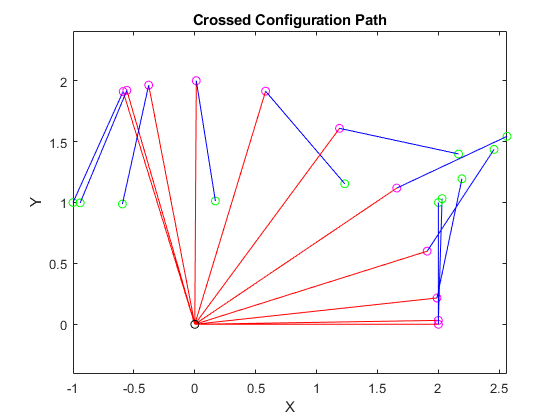

figure(23);  %crossed path
for i = (1:100:length(J2_xc))
    plot(0,0,'ko');
    axis equal
    hold on
    plot(J2_xc(i,1),J2_yc(i,1),'mo');
    hold on
    plot(ee_xc(i,1),ee_yc(i,1),'go');
    hold on
    plot([0,J2_xc(i,1)],[0,J2_yc(i,1)],'r-');   %first link positions
    hold on
    plot([J2_xc(i,1),ee_xc(i,1)],[J2_yc(i,1),ee_yc(i,1)],'b-')  %second link positions
    title('Crossed Configuration Path');
    xlabel('X');
    ylabel('Y');
end

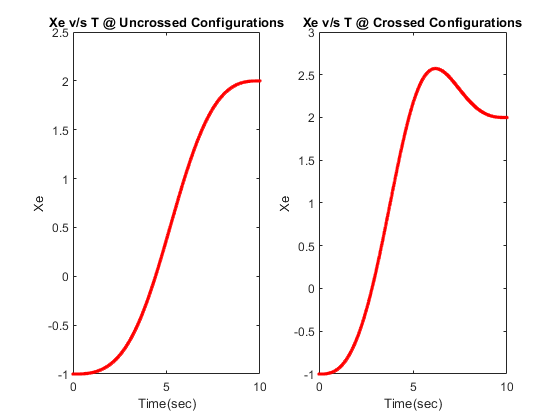

%(Di) Xe v/s t
figure(24);
subplot(1,2,1)
plot(t,ee_xu,'r.')
title('Xe v/s T @ Uncrossed Configurations');
xlabel('Time(sec)');
ylabel('Xe');
subplot(1,2,2)
plot(t,ee_xc,'r.')
title('Xe v/s T @ Crossed Configurations');
xlabel('Time(sec)');
ylabel('Xe');

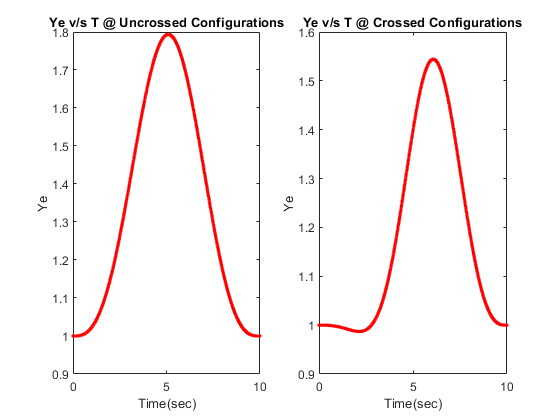

%(Dii) Ye v/s t
figure(25);
subplot(1,2,1)
plot(t,ee_yu,'r.')
title('Ye v/s T @ Uncrossed Configurations');
xlabel('Time(sec)');
ylabel('Ye');
subplot(1,2,2)
plot(t,ee_yc,'r.')
title('Ye v/s T @ Crossed Configurations');
xlabel('Time(sec)');
ylabel('Ye');

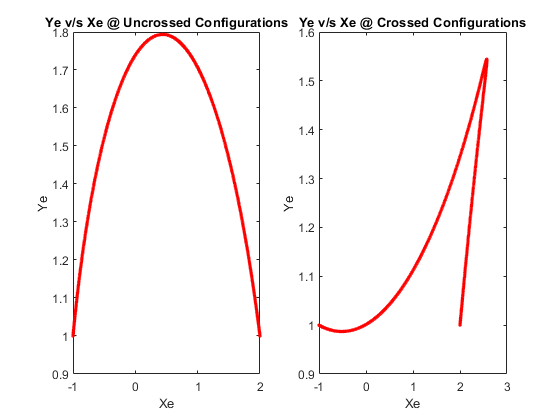

%(Diii) Ye v/s Xe
figure(26);
subplot(1,2,1)
plot(ee_xu,ee_yu,'r.')
title('Ye v/s Xe @ Uncrossed Configurations');
xlabel('Xe');
ylabel('Ye');
subplot(1,2,2)
plot(ee_xc,ee_yc,'r.')
title('Ye v/s Xe @ Crossed Configurations');
xlabel('Xe');
ylabel('Ye');

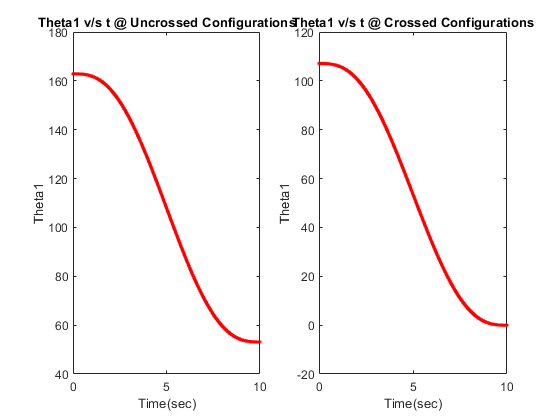

%(Div) theta1 v/s t
figure(27);
subplot(1,2,1)
plot(t,theta1_u,'r.')
title('Theta1 v/s t @ Uncrossed Configurations');
xlabel('Time(sec)');
ylabel('Theta1');
subplot(1,2,2)
plot(t,theta1_c,'r.')
title('Theta1 v/s t @ Crossed Configurations');
xlabel('Time(sec)');
ylabel('Theta1');

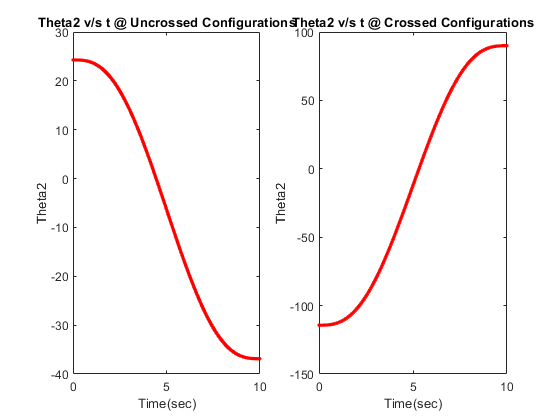

%(Dv) theta2 v/s t
figure(28);
subplot(1,2,1)
plot(t,theta2_u,'r.')
title('Theta2 v/s t @ Uncrossed Configurations');
xlabel('Time(sec)');
ylabel('Theta2');
subplot(1,2,2)
plot(t,theta2_c,'r.')
title('Theta2 v/s t @ Crossed Configurations');
xlabel('Time(sec)');
ylabel('Theta2');